% Load
clear all;
read = readcell("files\run0313");
results = cell2mat(read(3:length(read(:,1))-1,:));
waits = (1:length(results(:,1)));

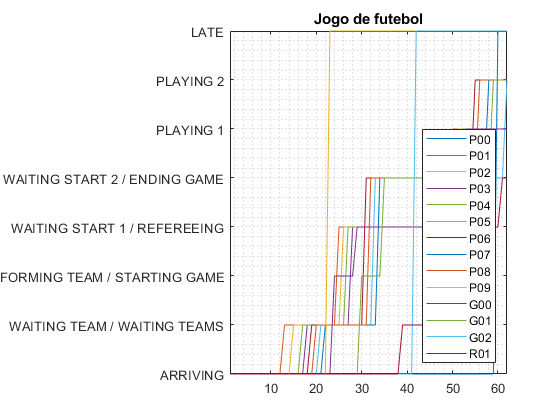

% Gráfico
for p = 1:length(results(1,:))
    plot(waits,results(:,p));
    hold on;
end
hold off;
grid("minor");
lgd = legend(read(2,:));
lgd.Location = 'southeast';
title("Jogo de futebol");
ay = gca;
states = ["ARRIVING","WAITING TEAM / WAITING TEAMS","FORMING TEAM / STARTING GAME","WAITING START 1 / REFEREEING","WAITING START 2 / ENDING GAME","PLAYING 1","PLAYING 2","LATE"];
ay.YTickLabel = states;
yticks(0:length(states));
axis(ay,"tight");

% Test

retVal1 = [];            % caso a ordem dos acontecimentos esteja errada retVal será igual ao teste em que a ordem de acontecimentos foram errados
retVal2 = [];            % caso os requisitos não tenham sido cumpridos

for test = 1:2000        
    % Load
    read = readcell(strcat("files\run",sprintf('%04.0f', test)));
    results = cell2mat(read(3:length(read(:,1))-1,:));
    waits = (1:length(results(:,1)));
    
    checks = 0;                                                                                                  % number of checks to make
    for w = waits(2:end)
        % numero de pessoas arriving, inicia uma unica vez
        if(w == 2)
            checks = checks + length(results(1,:));
        end
        
        % jogadores
        for player = 1:length(results(1,:)) - 1
            if(results(w,player) ~= results(w - 1,player))                                                       % caso aconteça uma transição de estado
                num = results(w,player);                                                                         % cópia do estado para k transitou
                switch(num)
                    case 1                                                                                       % espera pela criação das equipa
                        checks = checks + 1;                                                                     % adiciona 1 ao numero de pessoas à espera de equipa
                    case 2                                                                                       % criação de equipas
                        checks = checks - 4 + 1;                                                                 % elimina o numero de pessoas k estavam à espera de equipa e k entraram numa equipa e adiciona uma equipa
                    case 3                                                                                       % espera de começar o jogo equipa 1 
                        checks = checks + 1;                                                                     % acrescenta 1 ao numero de pessoas à espera de k o jogo comece
                    case 4                                                                                       % espera de começar o jogo equipa 2
                        checks = checks + 1;                                                                     % acrescenta 1 ao numero de pessoas à espera de k o jogo comece
                    case 5                                                                                       % equipa 1 começou a jogar
                        checks = checks + 1;                                                                     % acrescenta 1 ao numero de jogadores a jogar
                    case 6                                                                                       % equipa 1 começou a jogar
                        checks = checks + 1;                                                                     % acrescenta 1 ao numero de jogadores a jogar                    
                    case 7                                                                                       % chega atrasado
                        checks = checks - 1;                                                                     % elimina a sua existencia
                    otherwise
                        fprintf("ERRO in %d\n",num);
                end
            end
        end
        
        % Referee
        if(results(w,length(results(1,:))) ~= results(w - 1,length(results(1,:))))                               % caso aconteça uma transição de estado
            num1 = results(w,length(results(1,:)));                                                              % cópia do estado para k transitou
            switch(num1)
                case 1                                                                                           % espera pela criação das equipas
                    checks = checks + 0;                                                                         % n faz nada
                case 2                                                                                           % começa o jogo
                    checks = checks - 2;                                                                         % elimina o numero de equipas formadas
                case 3                                                                                           % arbitra o jogo
                    checks = checks - 10;                                                                        % elimina tds os k estavam á espera de começar a jogar
                case 4                                                                                           % acaba o jogo
                    checks = checks - 21;                                                                        % elimina tdas as pessoas em campo a jogar, e os arrives k jogaram incluindo ele
                case 7                                                                                           % chega atrasado
                    checks = checks - 1;                                                                         % elimina a sua existencia
                otherwise
                    fprintf("ERRO in %d\n",num);
            end
        end
        
        if(checks < 0)                                                                                           % encontrou-se uma ordem de acontecimentos errada
            retVal1 = [retVal1 test];                                                                            % sinaliza-se falta de ordem
        end
    end
    if (checks ~= 0)                                                                                             % encontrou-se um erro
        retVal2 = [retVal2 test];                                                                                % sinaliza-se mais um erro ao numero de erros encontrados
    end
end